## Multiplikative Modultion (Cosinus): Q-PSK Signal, Realteilbildung im Bandpass

% Alles löschen und aufräumen
close all; clear all; clc;
% Zusätzlich Pfad vom ersten Übungsblatt angeben -> Für plotfft
addpath('../../../60_Labor/01_Uebungsblatt_Musterloesung/');   
addpath('../../../60_Labor/02_Uebungsblatt_Musterloesung/');   

### Anlegen der Signale

% Festlegung der Parameter
fa = 50e3; Ta = 1 / fa;
fs = 1000; Ts = 1 / fs;
fc = 8000;

% Erstellen von zufälligen Bits
Nbits = 50;
bits = round(rand(1, Nbits), 0);

% Berechnung der Signallänge für reeller harmonische Schwingung
Nsym = Nbits;
N_samples = floor(Nsym * (Ts / Ta)); 
Tq = Ta * (N_samples / 2) - Ta;

% Erzeugung der Signale
yqpsk = PskGen(bits, fs, fa, 'QPSK');
yexp_q_mod = SigGen(Tq, fa, 'expj', fc);
yexp_q_demod = SigGen(Tq, fa, 'expj', -fc);

### Darstellung des Basisband-Signals

disp('Q-PSK Signal im Basisband');

Q-PSK Signal im Basisband


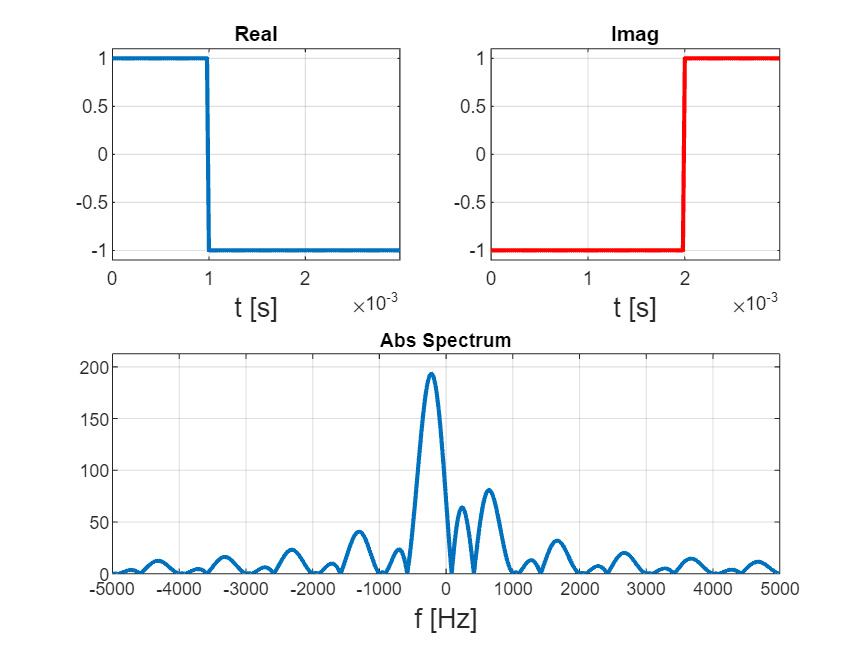

plotfft(yqpsk, fa, 'DisplaySignal', 'both', 'Nfft', 10240, 's', 1, 'Title', "Q-PSK-Signal im Basisband");
xlim([-5000, 5000]);

### Modulation des Signals

% Multiplikation der Signale
yqpsk_bp = yqpsk .* yexp_q_mod;

### Darstellung des Bandpass-Signals

disp('Q-PSK Signal im Bandpass');

Q-PSK Signal im Bandpass


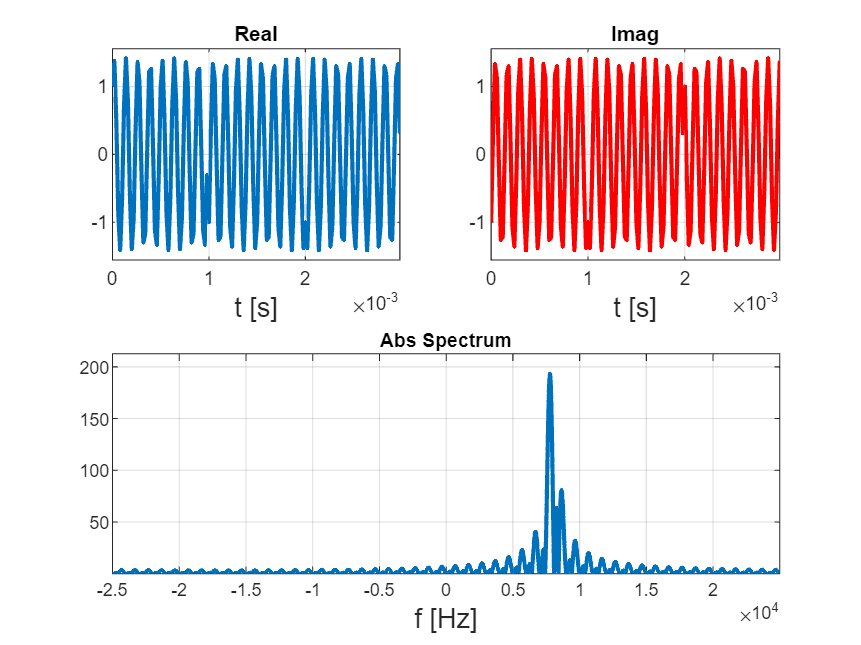

plotfft(yqpsk_bp, fa, 'DisplaySignal', 'both', 'Nfft', 10240, 's', 1, 'Title', "Q-PSK-Signal im Bandpass");

### Realteilbildung im Bandpass

**Achtung:** Hier kann der Realteil gebildet werden ohne das Information verloren geht! Das Spektrum des komplexen Bandpass-Signal besitzt bei der negativen Trägerfrequenz keine signifikanten Frequenzanteile, welche die Modulation durch die Realteilbildung zerstören würden.

Grundsätzlich ist das auch der Vorteil bei der Modulation in den komplexen Bandpass. Im Anschluss ist eine Realteilbildung möglich, sodass das Signal ohne Signalverlust mir nur einem Signal wiedergegeben werden kann.

Dafür wird jedoch im Basisband ein Tiefpass Filter nötig sein.

% Realteilbildung
yqpsk_bp_real = real(yqpsk_bp)

yqpsk_bp_real =     1.0000    1.3802    0.4790   -0.8668   -1.4079   -0.6420    0.7199    1.4135    0.7949   -0.5617   -1.3968   -0.9352    0.3946    1.3581    1.0608   -0.2212   -1.2979   -1.1697    0.0444    1.2173    1.2601    0.1331   -1.1174   -1.3306   -0.3085    1.0000    1.3802    0.4790   -0.8668   -1.4079   -0.6420    0.7199    1.4135    0.7949   -0.5617   -1.3968   -0.9352    0.3946    1.3581    1.0608   -0.2212   -1.2979   -1.1697    0.0444    1.2173    1.2601    0.1331   -1.1174   -1.3306   -0.3085


### Darstellung des Bandpass-Signals nach Realteilbildung

disp('Q-PSK Signal im Bandpass nach Realteilbildung');

Q-PSK Signal im Bandpass nach Realteilbildung


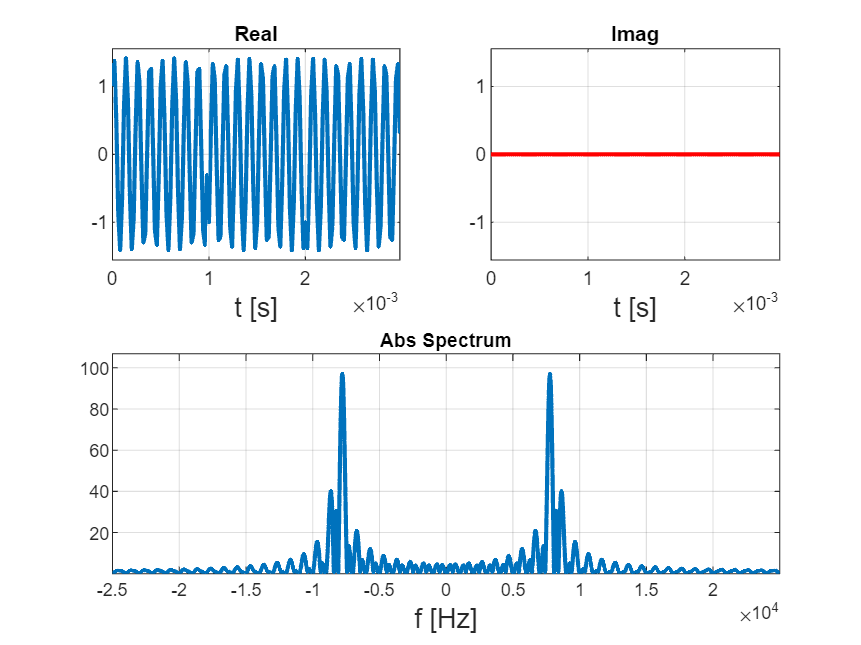

plotfft(yqpsk_bp_real, fa, 'DisplaySignal', 'both', 'Nfft', 10240, 's', 1, 'Title', "Q-PSK-Signal im Bandpass nach Realteilbildung");

### Demodulation des Signals

% Multiplikation der Signale
yqpsk_bb = yqpsk_bp_real .* yexp_q_demod;

### Darstellung des Demodulierten Basisband-Signals

disp('Q-PSK Signal im Basisband (Nach Demodulation)');

Q-PSK Signal im Basisband (Nach Demodulation)


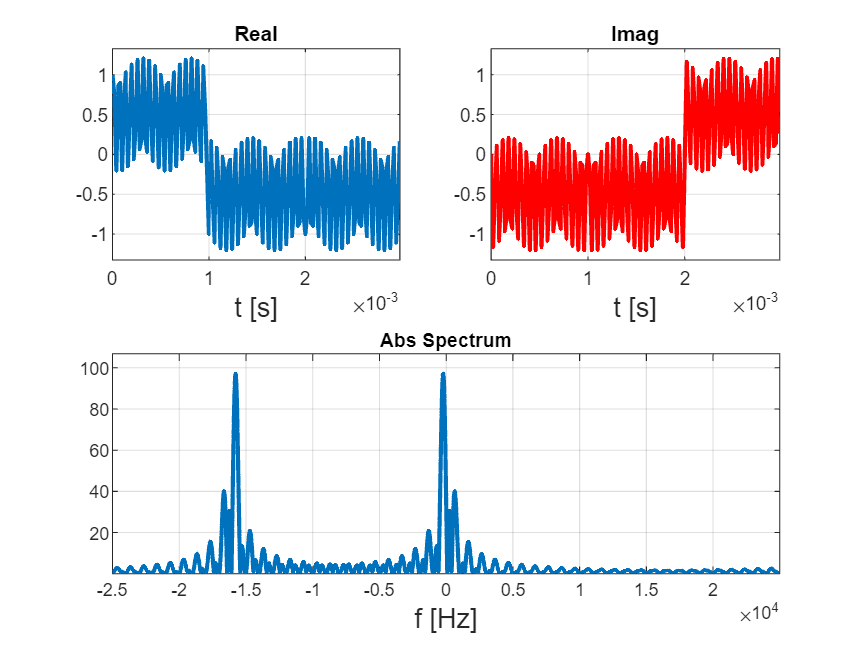

plotfft(yqpsk_bb, fa, 'DisplaySignal', 'both', 'Nfft', 10240, 's', 1, 'Title', "Q-PSK-Signal im Basisband (Nach Demodulation)");

### Anwendung des Tiefpasses

% Fir Filter Erstellen
firFilterObj = genFirFilter();
fir_coef = firFilterObj.Numerator;
fir_coef = fir_coef / sum(fir_coef);

% Fir Filter Anwenden
yqpsk_bb_fir = conv(yqpsk_bb, fir_coef);

% Ein- und Auschwingvorgänge entfernen
N_fir_half = floor (length(fir_coef) / 2);
yqpsk_bb_fir = yqpsk_bb_fir( N_fir_half : length(yqpsk_bb_fir) - N_fir_half);

### Darstellung des Demodulierten Tiefpass-Gefilterten Basisband-Signals

disp('Q-PSK Signal im Basisband (Nach Demodulation und nach Tiefpass)');

Q-PSK Signal im Basisband (Nach Demodulation und nach Tiefpass)


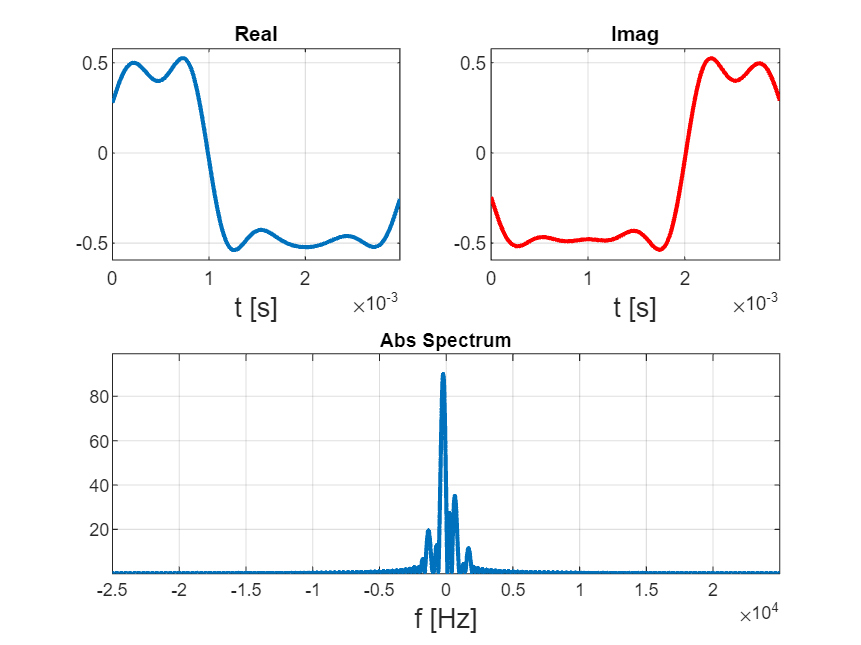

plotfft(yqpsk_bb_fir, fa, 'DisplaySignal', 'both', 'Nfft', 10240, 's', 1, 'Title', "Q-PSK-Signal im Basisband (Nach Demodulation und nach Tiefpass)");